# Activity Map_events_arena_binary 

Elapsed time is 0.459407 seconds.
Elapsed time is 0.612111 seconds.


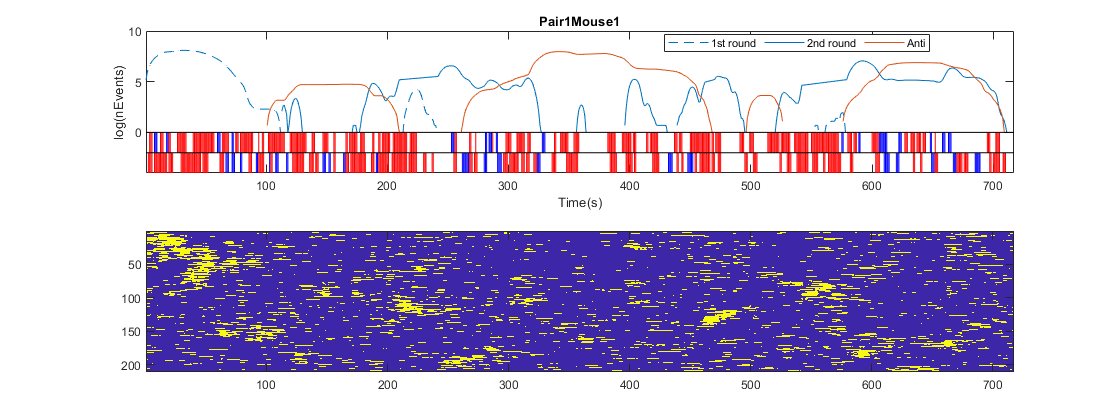

Elapsed time is 0.426045 seconds.
Elapsed time is 0.570445 seconds.


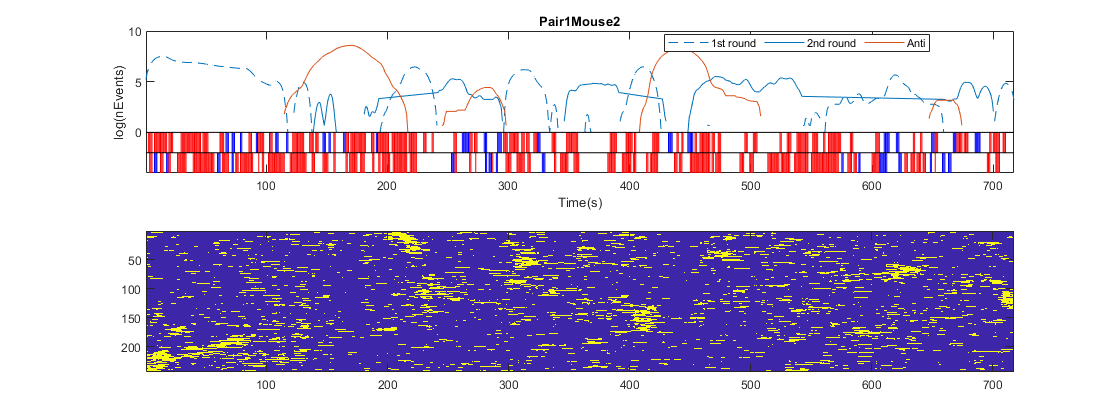

Elapsed time is 0.428068 seconds.
Elapsed time is 0.547568 seconds.


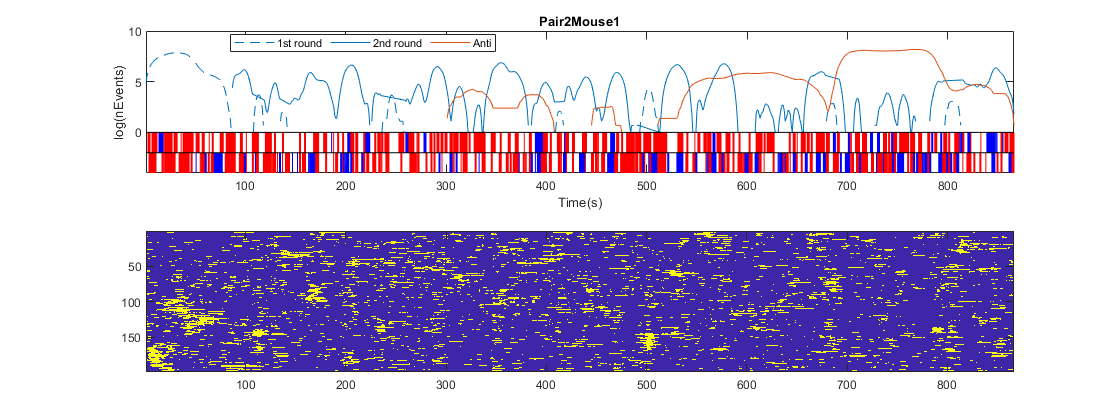

Elapsed time is 0.546073 seconds.
Elapsed time is 0.678210 seconds.


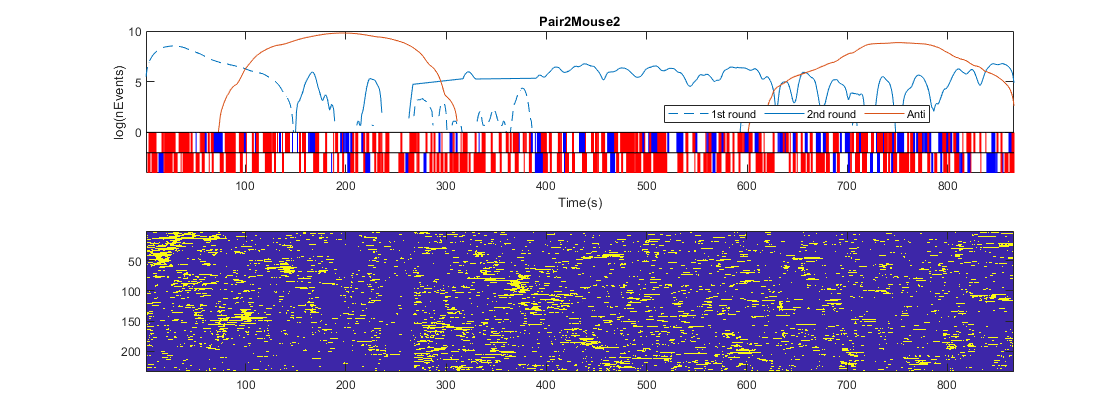

Elapsed time is 0.410839 seconds.
Elapsed time is 0.526571 seconds.


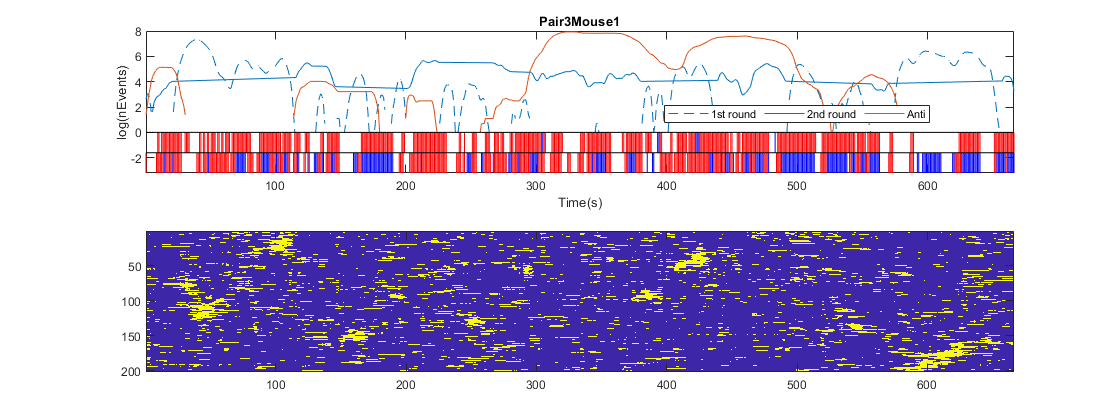

Elapsed time is 0.394339 seconds.
Elapsed time is 0.514887 seconds.


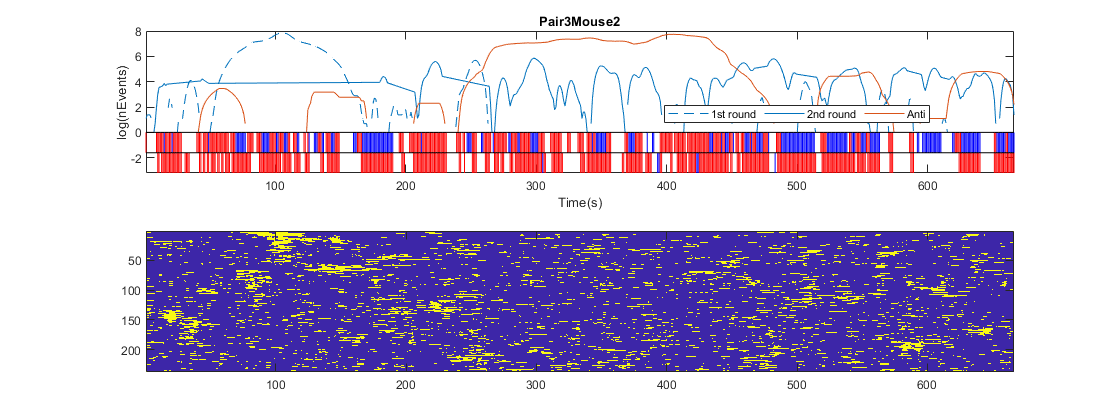

Elapsed time is 0.399660 seconds.
Elapsed time is 0.523216 seconds.


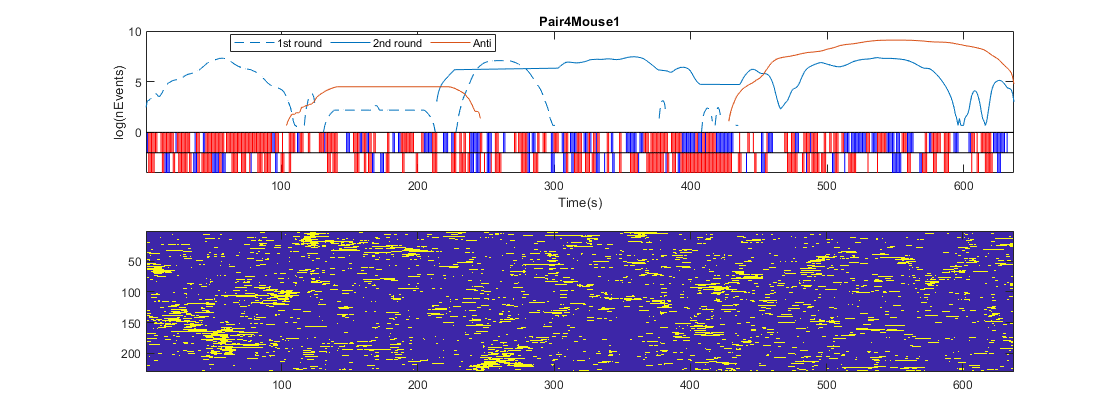

Elapsed time is 0.381593 seconds.
Elapsed time is 0.508176 seconds.


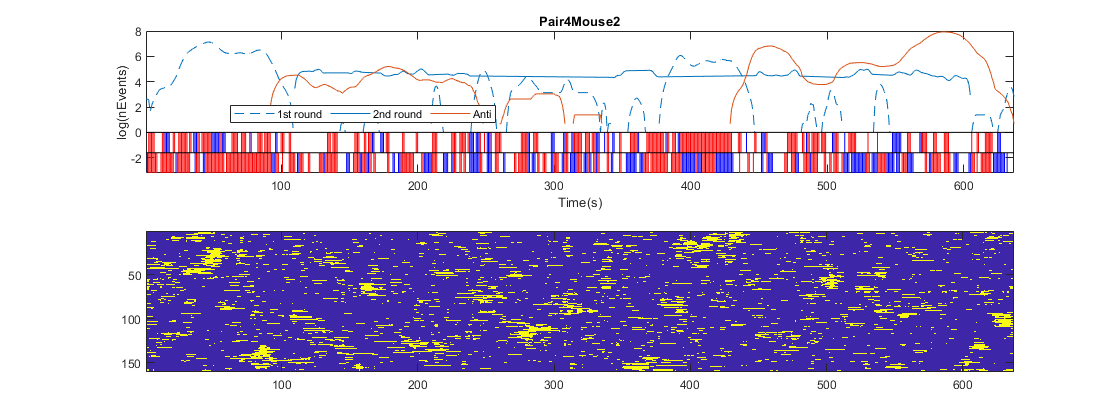

Elapsed time is 0.377692 seconds.
Elapsed time is 0.484220 seconds.


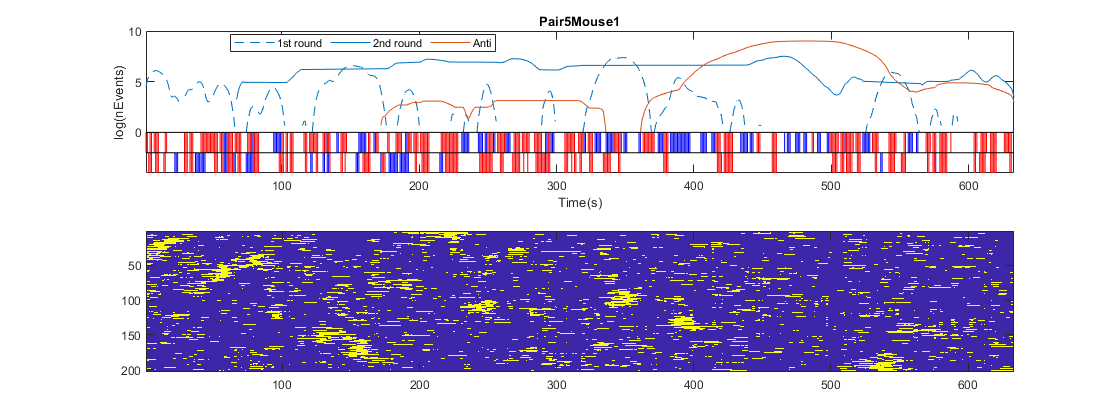

Elapsed time is 0.554937 seconds.
Elapsed time is 0.732301 seconds.


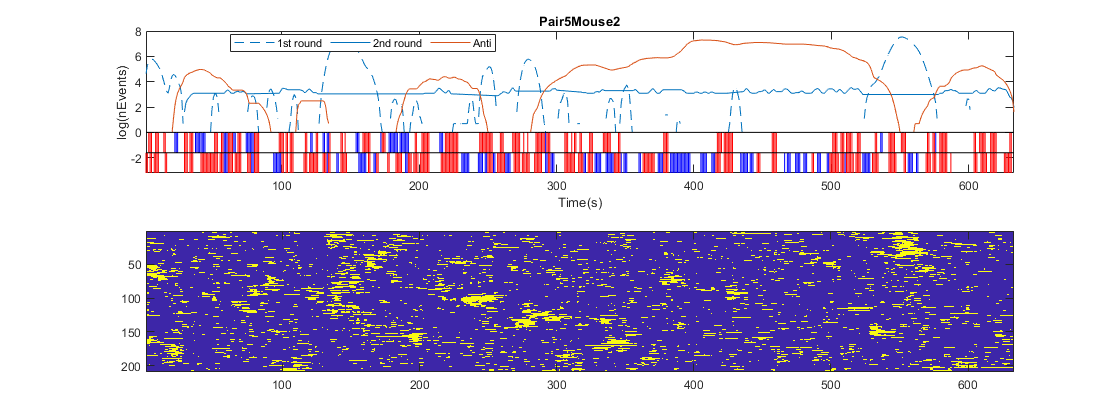

Elapsed time is 0.411112 seconds.
Elapsed time is 0.516077 seconds.


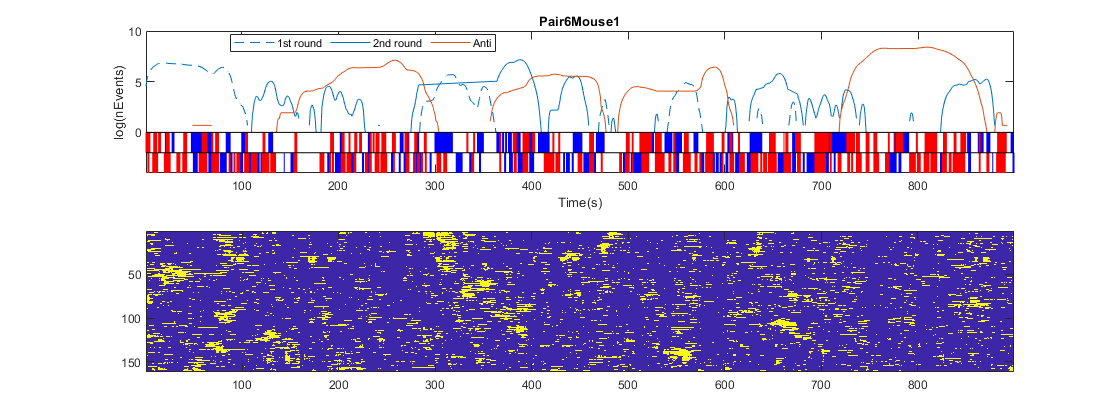

Elapsed time is 0.448416 seconds.
Elapsed time is 0.576635 seconds.


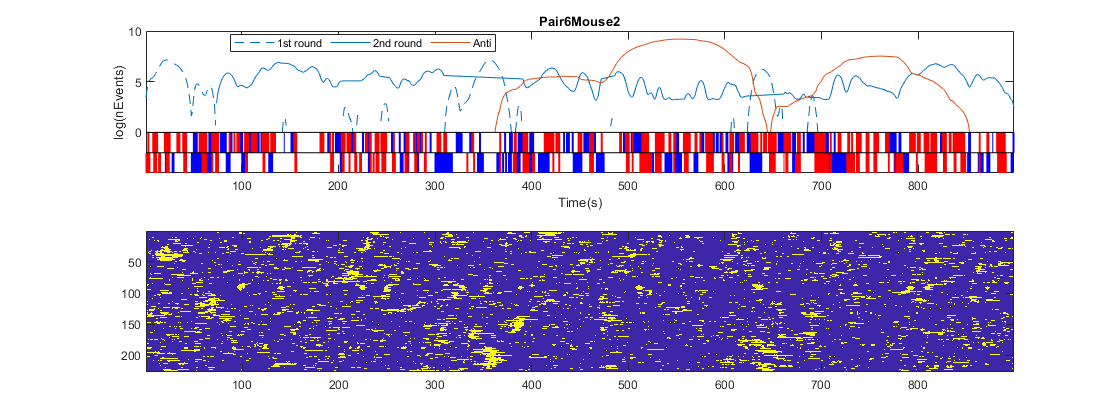

Elapsed time is 0.417231 seconds.
Elapsed time is 0.546859 seconds.


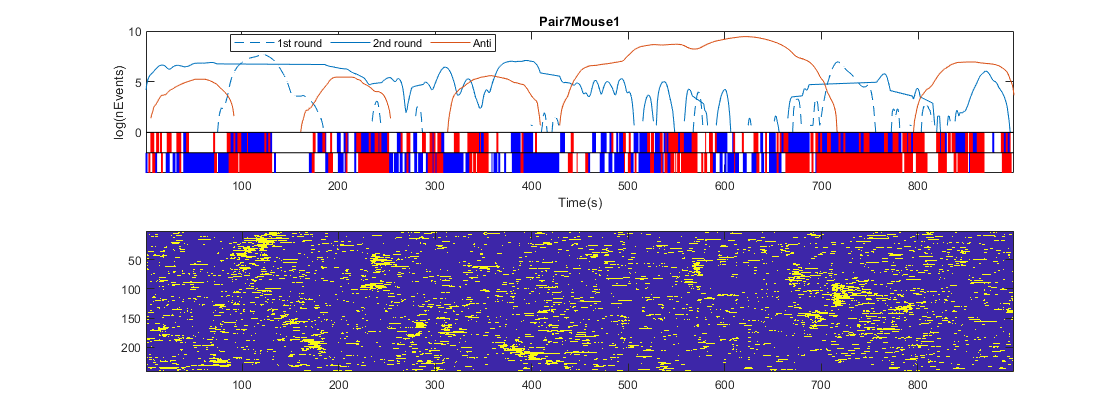

Elapsed time is 0.425629 seconds.
Elapsed time is 0.529993 seconds.


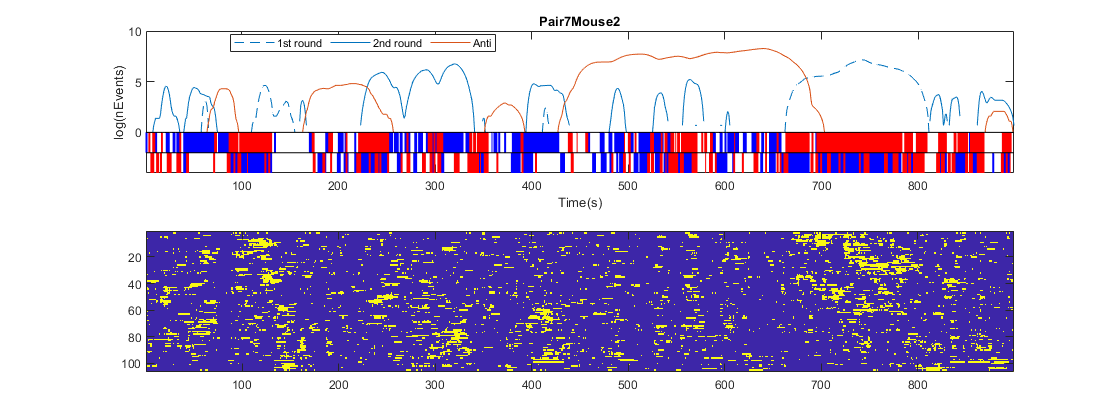

Elapsed time is 0.378877 seconds.
Elapsed time is 0.512089 seconds.


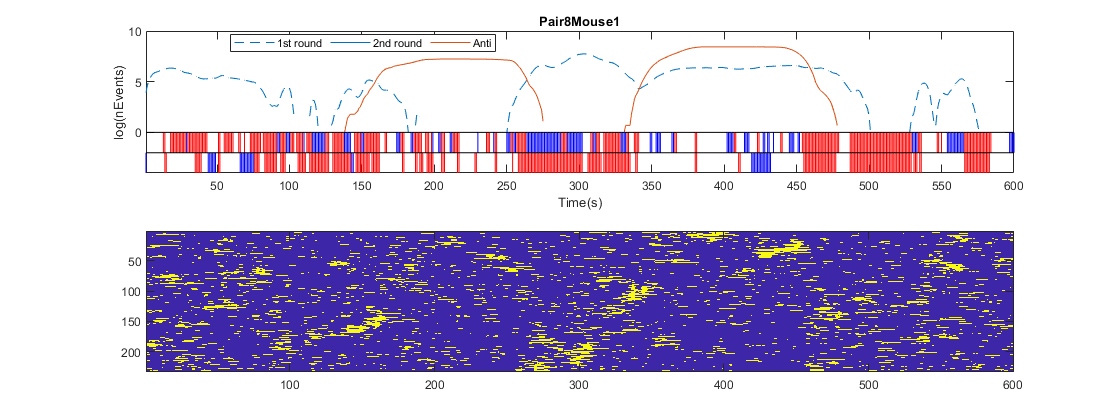

Elapsed time is 0.370962 seconds.
Elapsed time is 0.481737 seconds.


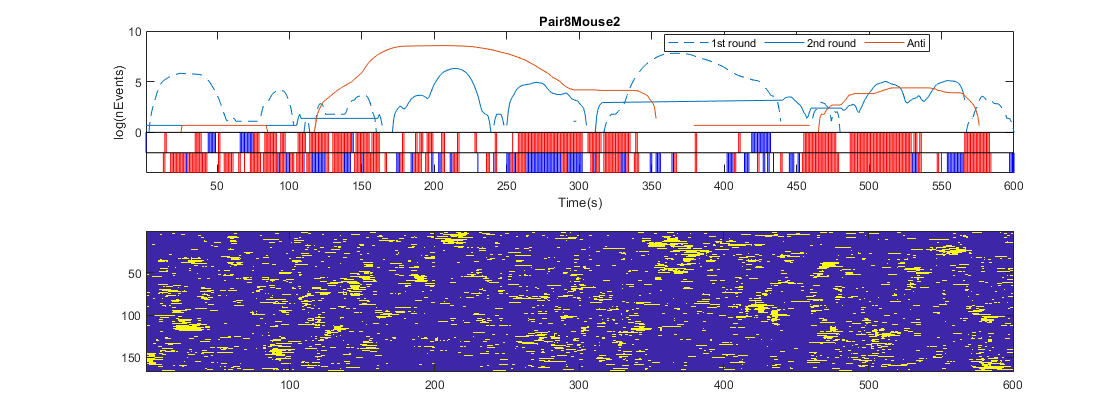

Elapsed time is 0.406407 seconds.
Elapsed time is 0.531155 seconds.


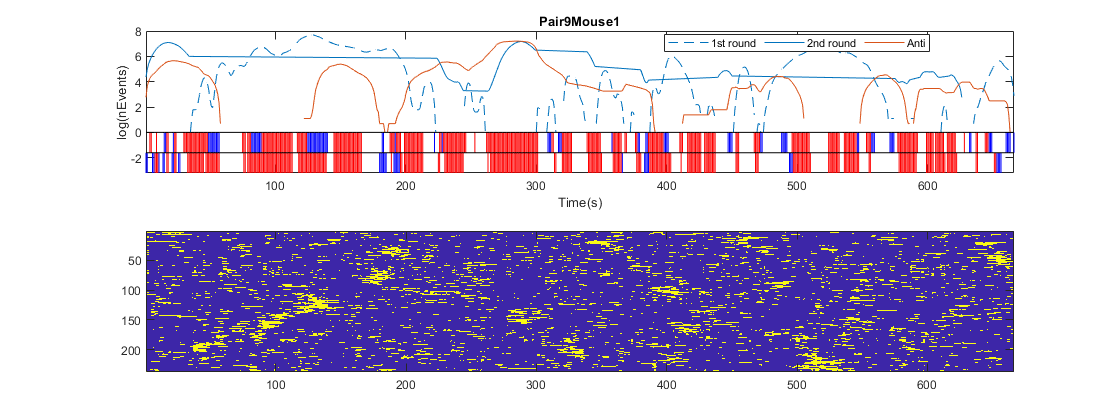

Elapsed time is 0.409572 seconds.
Elapsed time is 0.504960 seconds.


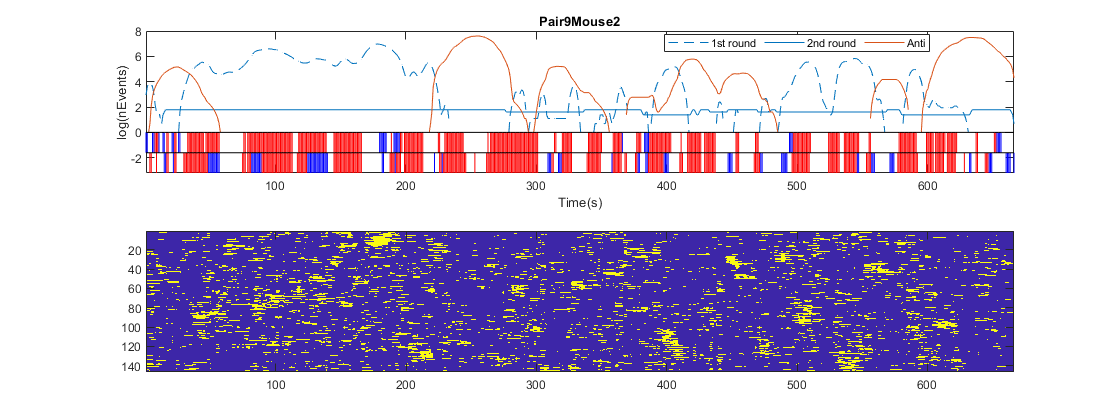

Elapsed time is 0.540907 seconds.
Elapsed time is 0.678381 seconds.


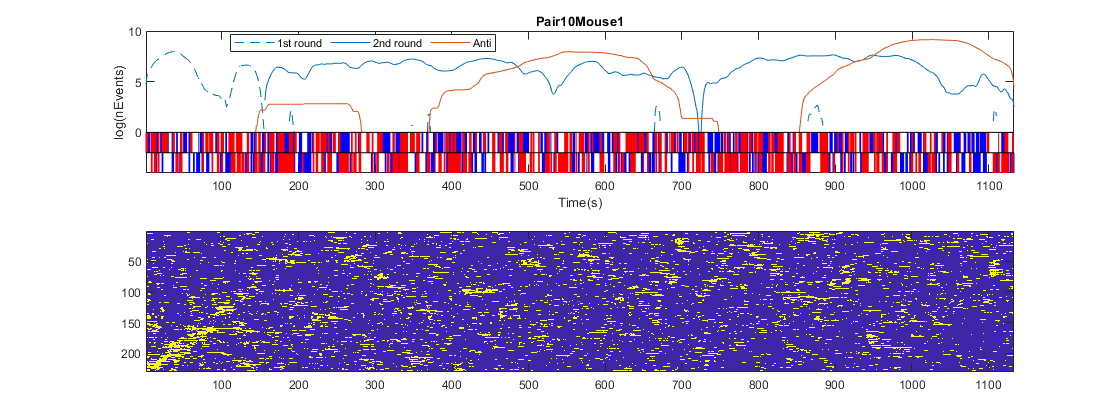

Elapsed time is 0.541141 seconds.
Elapsed time is 0.670611 seconds.


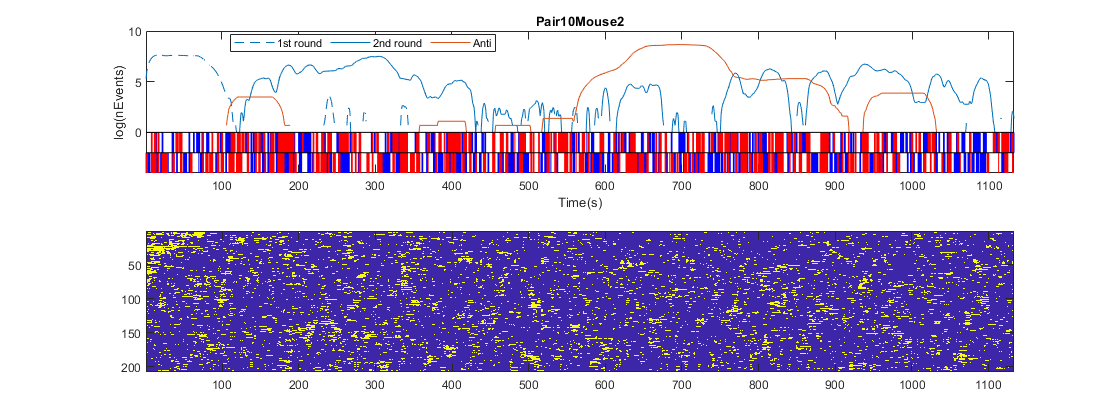

load('em_arena_antievent_binary_0.05.mat')
load('em_arena_binary_th0.5.mat')
load('HC_SYN_10Psocial_R1_030119_UPD.mat')
close all
ca_cl=em{1,1}.ca_cl;
N=10;
x=0;th=1;
for p=1:N
    for m=1:2
        sbename=E{p}{m}.BehaviorNames;obename=E{p}{setdiff([1 2],m)}.BehaviorNames;
        beh=E{p}{m}.BehaviorVectors; % self behaviour 
        opbeh=E{p}{setdiff([1 2],m)}.BehaviorVectors; % opponent behaviours 
        em1=em{1,1}.ne{p,m}';em2=em{2,1}.ne{p,m}';em2filter=em{2,1}.timefilter{p,m};antieve=anti{1,1}.ne{p,m}';
        x=x+1;f1=figure(x);f1.Position(3)=2*f1.Position(3);
        subplot(2,1,1)
        eventplot_arena(em1,em2,em2filter,antieve,beh,sbename,opbeh,obename,"logscale",true);
        title(sprintf('Pair%dMouse%d',p,m))
        subplot(2,1,2) % raster plot 
        S0=ca_cl{p,m};
        ops.iPC=1:35;
        [isort1, ~, ~] = mapTmap(S0, ops);
        imagesc(S0(isort1,:))
    end 
end